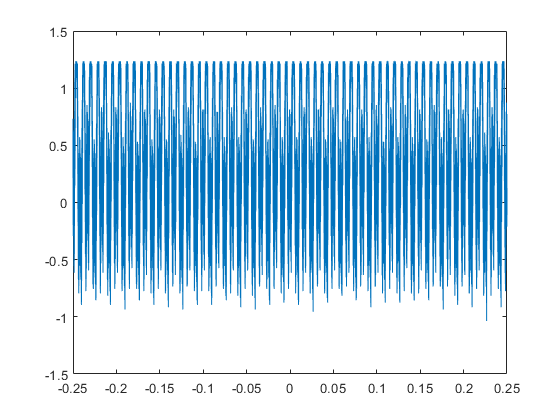

plot(t, y);

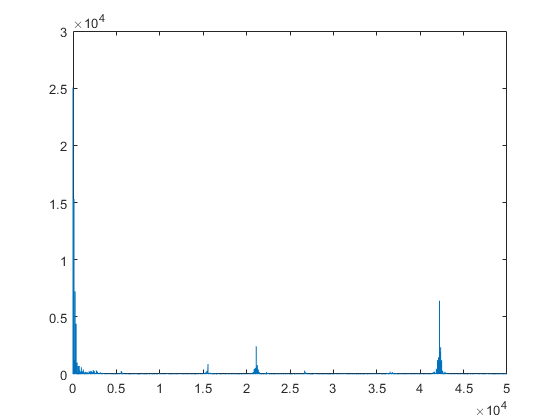

Y = fft(y);

Fs=1/max(diff(t));
L=length(Y);
Y1=Y(1:L/2);            %we take the first half of the vector
f=linspace(0,Fs/2,L/2); %we create the frequency vector
plot(f, abs(Y1));

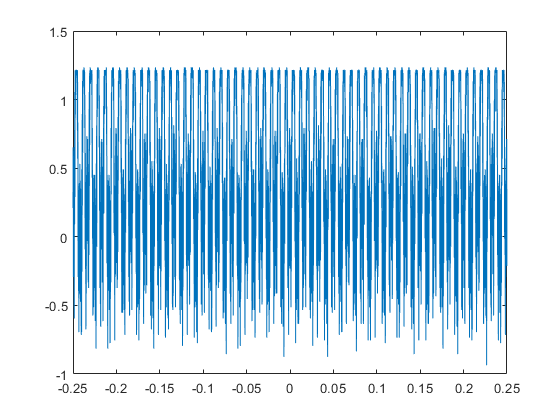





y_ds = y(1:10:length(y));
t_ds = t(1:10:length(t));
Fs_ds = Fs/10;

plot(t_ds, y_ds);

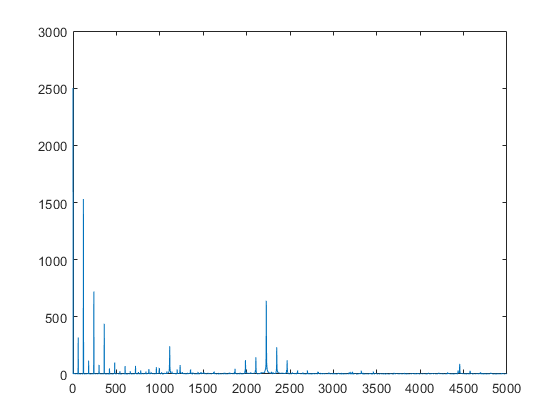


Y_ds = fft(y_ds);
L_ds=length(Y_ds);
Y1_ds=Y_ds(1:L_ds/2);            %we take the first half of the vector
f_ds=linspace(0,Fs_ds/2,L_ds/2); %we create the frequency vector
plot(f_ds, abs(Y1_ds));

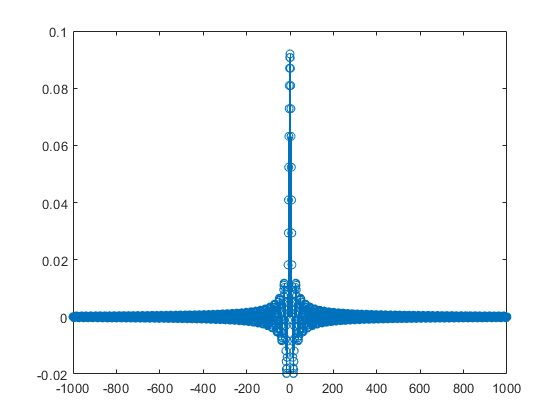









N = 2001; % total number of samples in the filter
L = (N-1)/2; % the filter will go from –L to L
n = (-L:L); % this is our sample index
f_corner = 4600; % corner frequency of our low-pass filter in Hz
f_s = 100000; % our sampling frequency in Hz
h_ideal_FIR = 2*f_corner/f_s*sinc(n*2*f_corner/f_s); % ideal sinc
% IMPORTANT: in the code above we convert f_corner from
% Hz to cycles/sample by dividing by f_s
stem(n, h_ideal_FIR);

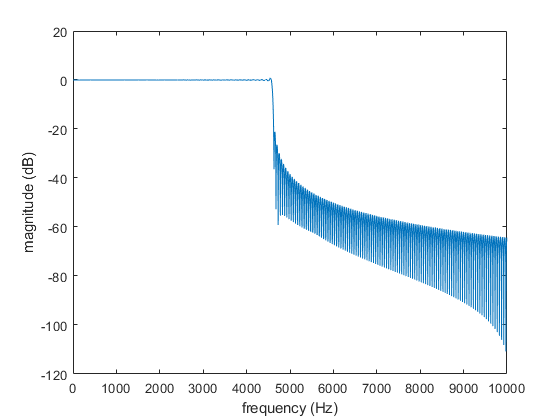




f_axis = linspace(0, 10000, 2000); % frequency axis with 2000 points
H_ideal_FIR = freqz(h_ideal_FIR, 1, f_axis, f_s);
% IMPORTANT: in the code above, the first two parameters
% to freqz are the b and a coefficients for the filter.
% Remember that the b coefficients for an FIR filter
% are just the impulse response values, and a_0 = 1 while
% all of the other a coefficients are zero.
plot(f_axis, 20*log10(abs(H_ideal_FIR)));
xlabel('frequency (Hz)');
ylabel('magnitude (dB)');

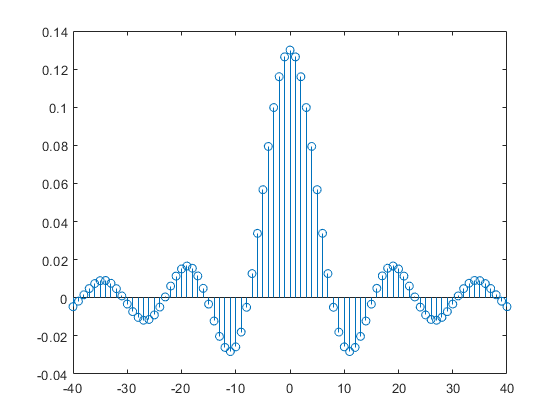





%real filter

w = chebwin(81);
N = 81; % total number of samples in the filter
L = (N-1)/2; % the filter will go from –L to L
n = (-L:L); % this is our sample index
f_corner = 6500; % corner frequency of our low-pass filter in Hz
f_s = 100000; % our sampling frequency in Hz
h_ideal_FIR = 2*f_corner/f_s*sinc(n*2*f_corner/f_s); % ideal sinc
% IMPORTANT: in the code above we convert f_corner from
% Hz to cycles/sample by dividing by f_s
b = w .* h_ideal_FIR';
stem(n, h_ideal_FIR);

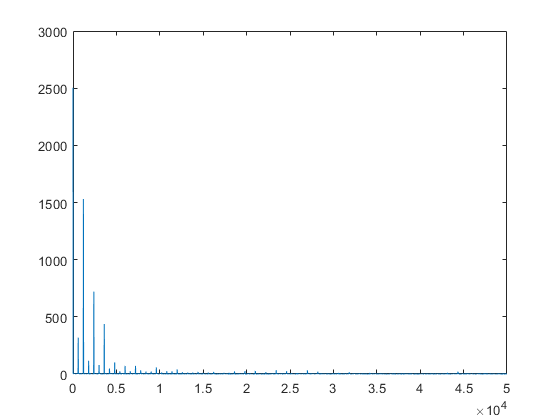


y_f = filter(b, 1, y);
y_f_ds = y_f(1:10:length(y_f));

Y_f_ds = fft(y_f_ds);

Fs=1/max(diff(t));
L=length(Y_f_ds);
Y1_f_ds=Y_f_ds(1:L/2);            %we take the first half of the vector
f=linspace(0,Fs/2,L/2); %we create the frequency vector
plot(f, abs(Y1_f_ds));


save FIR_b.txt b -ascii -double
